load("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\TrainingSamplesDCT_8.mat")

% Compute priors
prob_bg = size(TrainsampleDCT_BG, 1) / (size(TrainsampleDCT_BG, 1) + size(TrainsampleDCT_FG, 1))

prob_bg = 0.8081

prob_fg = size(TrainsampleDCT_FG, 1) / (size(TrainsampleDCT_BG, 1) + size(TrainsampleDCT_FG, 1))

prob_fg = 0.1919

bg_train_indices = find2ndLargest(TrainsampleDCT_BG)

bg_train_indices =      2     3     6     3     2     2     3     5     3     3     2     6     3     3     6     4     9     8     2     6     2     3     3    13     5     3     3     3     2     3     6     3     2     7     5     3     3     2     5     8     3     2     7     3     2     3     3     3     2     3


fg_train_indices = find2ndLargest(TrainsampleDCT_FG)

fg_train_indices =      2    33     7     6     8     2     3    12     8     5     7     3     4     7     2     3     3     2     3     9     9     2    14     2     3    19     6    16    14    16    19     3     3    14     7     7    13     9     6     3     2    18    15     8    15     7     3    18     8     3


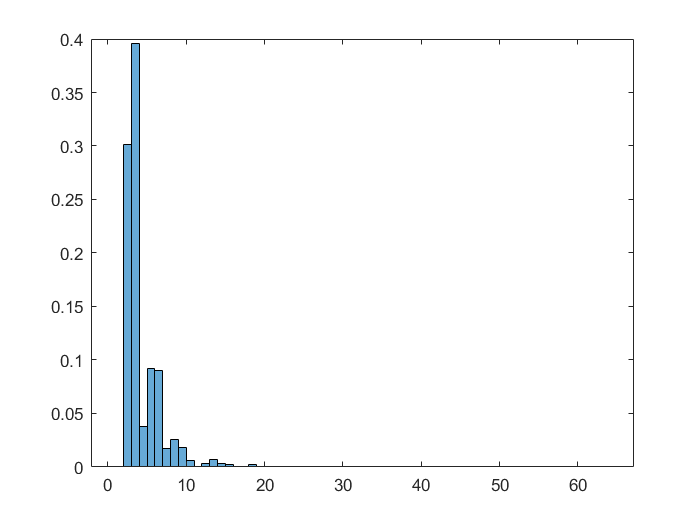

h_bg =   Histogram with properties:

             Data: [1×1053 double]
           Values: [0 0.3010 0.3960 0.0380 0.0921 0.0902 0.0171 0.0256 0.0180 0.0057 0 0.0028 0.0066 0.0028 0.0019 0 0 0.0019 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0]
          NumBins: 63
         BinEdges: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64]
         BinWidth: 1
        BinLimits: [1 64]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties



h_bg = histogram(bg_train_indices, 64, "BinEdges", [1:64], 'Normalization','probability')

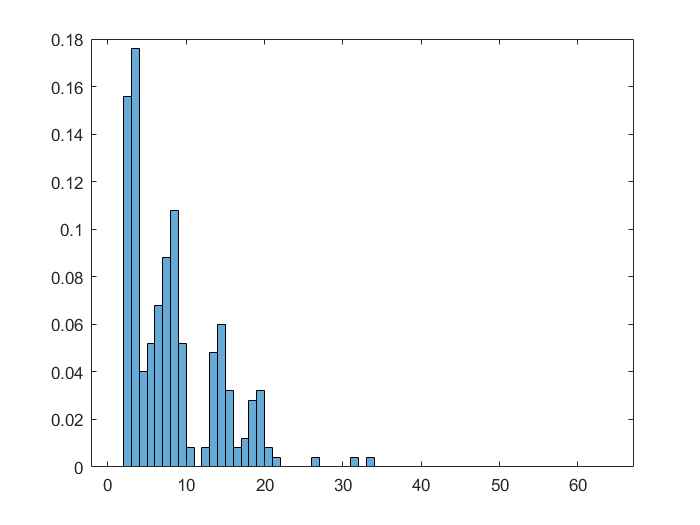

h_fg =   Histogram with properties:

             Data: [1×250 double]
           Values: [1×63 double]
          NumBins: 63
         BinEdges: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64]
         BinWidth: 1
        BinLimits: [1 64]
    Normalization: 'probability'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


h_fg = histogram(fg_train_indices, 64, "BinEdges", [1:64], 'Normalization','probability')

% Compute likelihood
prob_x_bg = histcounts(bg_train_indices, [1:65])

prob_x_bg =      0   317   417    40    97    95    18    27    19     6     0     3     7     3     2     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_x_bg = prob_x_bg / sum(prob_x_bg)

prob_x_bg =          0    0.3010    0.3960    0.0380    0.0921    0.0902    0.0171    0.0256    0.0180    0.0057         0    0.0028    0.0066    0.0028    0.0019         0         0    0.0019         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_x_fg = histcounts(fg_train_indices, [1:65])

prob_x_fg =      0    39    44    10    13    17    22    27    13     2     0     2    12    15     8     2     3     7     8     2     1     0     0     0     0     1     0     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_x_fg = prob_x_fg / sum(prob_x_fg)

prob_x_fg =          0    0.1560    0.1760    0.0400    0.0520    0.0680    0.0880    0.1080    0.0520    0.0080         0    0.0080    0.0480    0.0600    0.0320    0.0080    0.0120    0.0280    0.0320    0.0080    0.0040         0         0         0         0    0.0040         0         0         0         0    0.0040         0    0.0040         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


% ZigZagPattern = ZigZagPattern - 1
% ZigZagPattern = int8(ZigZagPattern)

img = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah.bmp")

img = 255×270 uint8 matrix
    61    60    51    46    47    48    50    60    57    61    68    69    69    71    78    83    88    94    97    97    98    94    88    86    87    90    99   106   113   114   116   117   120   122   124   125   124   124   125   123   121   124   127   129   132   135   137   131   126   123
    60    60    55    48    50    52    55    66    62    65    72    72    75    76    85    90    95   100   102   102   103   100    96    92    90    92   100   109   116   118   119   119   120   121   125   126   125   125   126   125   124   124   126   128   132   133   135   132   129   123
    62    61    58    51    54    57    61    71    67    71    77    76    81    83    91    98   102   105   106   107   110   107   104    99    97    96   102   110   118   121   122   119   119   120   123   125   125   125   125   125   124   126   126   129   131   133   132   132   129   126
    66    65    63    57    59    64    72    81    73    77    84    

img = im2double(img)

img =     0.2392    0.2353    0.2000    0.1804    0.1843    0.1882    0.1961    0.2353    0.2235    0.2392    0.2667    0.2706    0.2706    0.2784    0.3059    0.3255    0.3451    0.3686    0.3804    0.3804    0.3843    0.3686    0.3451    0.3373    0.3412    0.3529    0.3882    0.4157    0.4431    0.4471    0.4549    0.4588    0.4706    0.4784    0.4863    0.4902    0.4863    0.4863    0.4902    0.4824    0.4745    0.4863    0.4980    0.5059    0.5176    0.5294    0.5373    0.5137    0.4941    0.4824
    0.2353    0.2353    0.2157    0.1882    0.1961    0.2039    0.2157    0.2588    0.2431    0.2549    0.2824    0.2824    0.2941    0.2980    0.3333    0.3529    0.3725    0.3922    0.4000    0.4000    0.4039    0.3922    0.3765    0.3608    0.3529    0.3608    0.3922    0.4275    0.4549    0.4627    0.4667    0.4667    0.4706    0.4745    0.4902    0.4941    0.4902    0.4902    0.4941    0.4902    0.4863    0.4863    0.4941    0.5020    0.5176    0.5216    0.5294    0.5176    0.5059   


% Zero Padding
% right = zeros(255, 7);
% bottom = zeros(7, 277);
% img_pad = [[img right]; bottom]

img_pad =     0.2392    0.2353    0.2000    0.1804    0.1843    0.1882    0.1961    0.2353    0.2235    0.2392    0.2667    0.2706    0.2706    0.2784    0.3059    0.3255    0.3451    0.3686    0.3804    0.3804    0.3843    0.3686    0.3451    0.3373    0.3412    0.3529    0.3882    0.4157    0.4431    0.4471    0.4549    0.4588    0.4706    0.4784    0.4863    0.4902    0.4863    0.4863    0.4902    0.4824    0.4745    0.4863    0.4980    0.5059    0.5176    0.5294    0.5373    0.5137    0.4941    0.4824
    0.2353    0.2353    0.2157    0.1882    0.1961    0.2039    0.2157    0.2588    0.2431    0.2549    0.2824    0.2824    0.2941    0.2980    0.3333    0.3529    0.3725    0.3922    0.4000    0.4000    0.4039    0.3922    0.3765    0.3608    0.3529    0.3608    0.3922    0.4275    0.4549    0.4627    0.4667    0.4667    0.4706    0.4745    0.4902    0.4941    0.4902    0.4902    0.4941    0.4902    0.4863    0.4863    0.4941    0.5020    0.5176    0.5216    0.5294    0.5176    0.505

left = zeros(255, 3);
right = zeros(255, 4);
up = zeros(3, 277);
bottom = zeros(4, 277);
img_pad = [up; [left img right]; bottom]

% DCT
img_dct = dct_8(img, img_pad);
img_dct = abs(img_dct)

img_dct =     2.0985    0.0719    0.1455    0.0195    0.0103    0.0283    0.0092    0.0067    2.1176    0.1381    0.0925    0.0524    0.0088    0.0341    0.0330    0.0043    2.1740    0.2172    0.0339    0.0308    0.0270    0.0170    0.0576    0.0213    2.2721    0.2803    0.0100    0.0432    0.0505    0.0307    0.0259    0.0318    2.3838    0.2762    0.0019    0.0431    0.0132    0.0544    0.0135    0.0325    2.4897    0.2545    0.0203    0.0105    0.0564    0.0248    0.0419    0.0234    2.5902    0.2179
    0.2924    0.0410    0.0224    0.0195    0.0060    0.0158    0.0048    0.0040    0.3014    0.0309    0.0371    0.0083    0.0002    0.0049    0.0127    0.0061    0.3341    0.0336    0.0009    0.0407    0.0177    0.0219    0.0004    0.0038    0.3618    0.0382    0.0319    0.0289    0.0051    0.0177    0.0148    0.0023    0.3775    0.0461    0.0284    0.0109    0.0298    0.0033    0.0148    0.0013    0.3859    0.0464    0.0011    0.0377    0.0020    0.0199    0.0100    0.0049    0.391


% ZigZag Scan
img_scan = blockproc(img_dct, [8 8], @(block_struct) ZigZagScan(block_struct.data, ZigZagPattern))

img_scan =     2.0985    0.0719    0.2924    0.0239    0.0410    0.1455    0.0195    0.0224    0.0621    0.0068    0.0142    0.0109    0.0112    0.0195    0.0103    0.0283    0.0060    0.0161    0.0040    0.0042    0.0038    0.0129    0.0108    0.0120    0.0021    0.0148    0.0158    0.0092    0.0067    0.0048    0.0026    0.0032    0.0006    0.0004    0.0077    0.0032    0.0069    0.0072    0.0011    0.0015    0.0019    0.0032    0.0040    0.0043    0.0034    0.0007    0.0051    0.0064    0.0041    0.0003
    2.2137    0.0760    0.2740    0.0429    0.0119    0.1394    0.0140    0.0232    0.0668    0.0318    0.0020    0.0086    0.0008    0.0283    0.0098    0.0223    0.0104    0.0059    0.0139    0.0021    0.0055    0.0093    0.0130    0.0013    0.0058    0.0069    0.0141    0.0112    0.0078    0.0045    0.0033    0.0083    0.0007    0.0086    0.0057    0.0092    0.0070    0.0042    0.0029    0.0078    0.0027    0.0042    0.0013    0.0024    0.0013    0.0040    0.0010    0.0041    0.00

features = blockproc(img_scan, [1, 64], @(block_struct) find2ndLargest(block_struct.data));
features = int8(features)

features = 255×270 int8 matrix
    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    3    2    2    2    2    2    7    5    2    2    2    2    6    8    7    6    2    2    2    2    6    6    2    2    2    6    6    2
    3    3    3    3    3    3    3    3    3    3    3    3    3    2    4    4    4    4    3    3    3    3    2    2    2    2    2    6    7    3    6    2    2    2    6    8    3    6    2    2    2    2    6    6    2    2    2    6    6    5
    3    3    3    2    2    2    3    3    3    3    3    5    5    2    2    4    4    4    5    5    3    8    2    2    2    2    2    6    3    3    6    2    2    2    3    3    3    3    2    2    2    2    2    5    5    2    2    8    8    5
    3    3    2    2    2    2    2    3    3    3    5    5    5    5    2    2    2    2    5    5    5    8    8    2    2    2    2    6    3    3    3    3    2    2    3    3    3    3    3    2    2    2    2 


% Create binary mask using BDR
mask = blockproc(features, [1, 1], @(block_struct) BDR(block_struct.data, prob_x_bg, prob_x_fg, prob_bg, prob_fg));
mask = int8(mask)

mask = 255×270 int8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

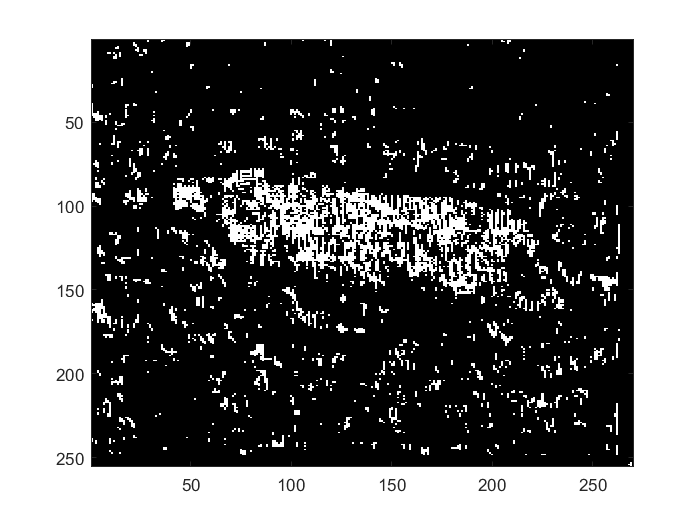

imagesc(mask)
colormap(gray(255))

ground_truth = imread("C:\Users\Muriate_C\Desktop\ECE 271A\HW1\cheetah_mask.bmp")

ground_truth = 255×270 uint8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

ground_truth = im2double(ground_truth)

ground_truth =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    

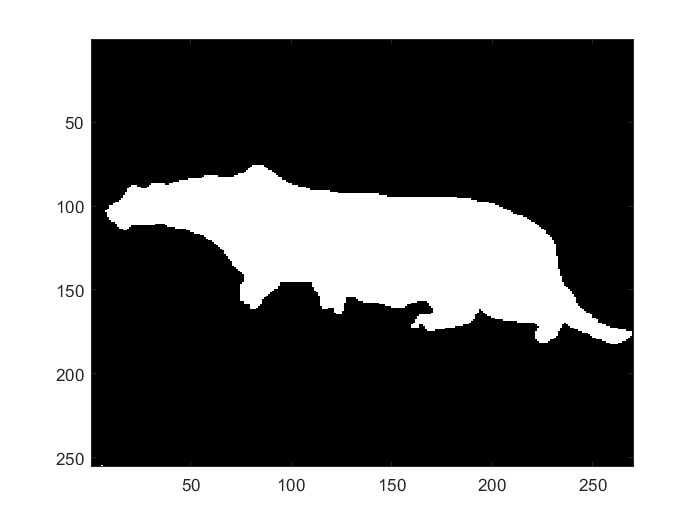

imagesc(ground_truth)
colormap(gray(255))


ground_truth = int8(ground_truth)

ground_truth = 255×270 int8 matrix
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 


% Compute probability of errors
% Method 1
p_error = 0;
diff = ground_truth - mask

diff = 255×270 int8 matrix
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -1    0    0    0    0    0    0   -1   -1    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -1    0    0    0    0    0    0   -1    0    0    0    0    0    0    0    0    0    0    0    0    0    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -1    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -1   -1    0
    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0   -1   -1    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0    0

diff_feature = features .* diff

diff_feature = 255×270 int8 matrix
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -7     0     0     0     0     0     0    -8    -7     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -7     0     0     0     0     0     0    -8     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -8     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    -8    -8     0
     0     0     0     0     0     0     0     0     0     0  

false_fg = int8.empty;
false_bg = int8.empty;
x = (1:64);
for i = 1:size(diff_feature, 1)
    for j = 1:size(diff_feature, 2)
        if diff_feature(i, j) < 0 % Find false foreground (ground truth:0, predicted Y:1)
            false_fg = [false_fg -diff_feature(i, j)];
        end
        if diff_feature(i, j) > 0 % Find false background (ground truth:1, predicted Y:0)
            false_bg = [false_bg diff_feature(i, j)];
        end
    end
end
false_fg_x = intersect(x, false_fg)

false_fg_x = 1×11 int8 row vector
    7    8   13   14   15   16   17   18   19   20   26


false_bg_x = intersect(x, false_bg)

false_bg_x = 1×20 int8 row vector
    1    2    3    4    5    6    9   10   11   12   23   24   25   27   28   29   30   32   41   42


for i = 1:length(x)
    p_error = p_error + prob_x_bg(1, i) * prob_bg * ismember(i, false_fg_x) ...,
            + prob_x_fg(1, i) * prob_fg * ismember(i, false_bg_x);
end
p_error

p_error = 0.1527


% Method 2
p_error_1 = 0;
for i = 1:64
    p_error_1 = p_error_1 + min(prob_x_bg(1, i) * prob_bg, prob_x_fg(1, i) * prob_fg);
end
p_error_1

p_error_1 = 0.1527


% Method 3
p_fg_gt = sum(sum(ground_truth==1)) / (size(ground_truth, 1) * size(ground_truth, 2));
p_bg_gt = sum(sum(ground_truth==0)) / (size(ground_truth, 1) * size(ground_truth, 2));
p_error_2 = sum(sum(diff==1)) / sum(sum(ground_truth==1)) * p_fg_gt + sum(sum(diff==-1)) / sum(sum(ground_truth==0)) * p_bg_gt

p_error_2 = 0.1726

p_error_3 = 1 - sum(sum(mask==ground_truth)) / (size(ground_truth, 1) * size(ground_truth, 2))

p_error_3 = 0.1726

function vector = ZigZagScan(matrix, pattern)
    vector = zeros(1, size(matrix, 1) * size(matrix, 2));
    for i = 1:size(matrix, 1)
        for j = 1:size(matrix, 2)
            position = pattern(i, j);
            vector(1, position) = matrix(i, j);
        end
    end
end

function indices = find2ndLargest(sample)
    indices = zeros(1, size(sample, 1));
    for i = 1:size(sample, 1)
        [~, index] = maxk(sample(i, :), 2);
        indices(1, i) = indices(1, i) + index(1, 2);
    end
end

function mask = BDR(feature, P_x_bg, P_x_fg, P_bg, P_fg)
    if P_x_bg(1, feature) * P_bg >= P_x_fg(1, feature) * P_fg
        mask = 0;
    else
        mask = 1;
    end
end

function dct = dct_8(img, img_pad)
    dct = zeros(size(img, 1) * 8, size(img, 2) * 8);
    for i = 1:size(img, 1)
        for j = 1:size(img, 2)
            dct((8*i-7):(8*i), (8*j-7):(8*j)) = dct2(img_pad(i:i+7, j:j+7));
        end
    end
end